## Numerical Comparison

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey

f = @(t,P,Z) a*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
P0 = prey * (1 + 0.5*rand(Nx,Ny));
Z0 = predator * (1 + 0.5*rand(Nx,Ny));
Dp = 1e-5; Dz = 1e-5;
n = 500; t_end = 24;
iter = 10;

tEuler = zeros(1,iter);
tEulerS = zeros(1,iter);
tCN = zeros(1,iter);
tADI = zeros(1,iter);

nVec = round(linspace(50,n,iter));

for i = 1:iter
    start = cputime();
    [t,P,Z] = EulerDiffusion(f,g, P0, Z0, Dp, Dz, t_end, nVec(i));
    tEuler(i) = cputime() - start;
end

for i = 1:iter
    start = cputime();
    [t,P,Z] = EulerDiffusionSparce(f,g, P0, Z0, Dp, Dz, t_end, nVec(i));
    tEulerS(i) = cputime() - start;
end

for i = 1:iter
    start = cputime();
    [t,P,Z] = CrankNicolsonDiffusion(f,g, P0, Z0, Dp, Dz, t_end, nVec(i));
    tCN(i) = cputime() - start;
end

for i = 1:iter
    start = cputime();
    [t,P,Z] = ADIDiffusion(f,g, P0, Z0, Dp, Dz, t_end, nVec(i));
    tADI(i) = cputime() - start;
end

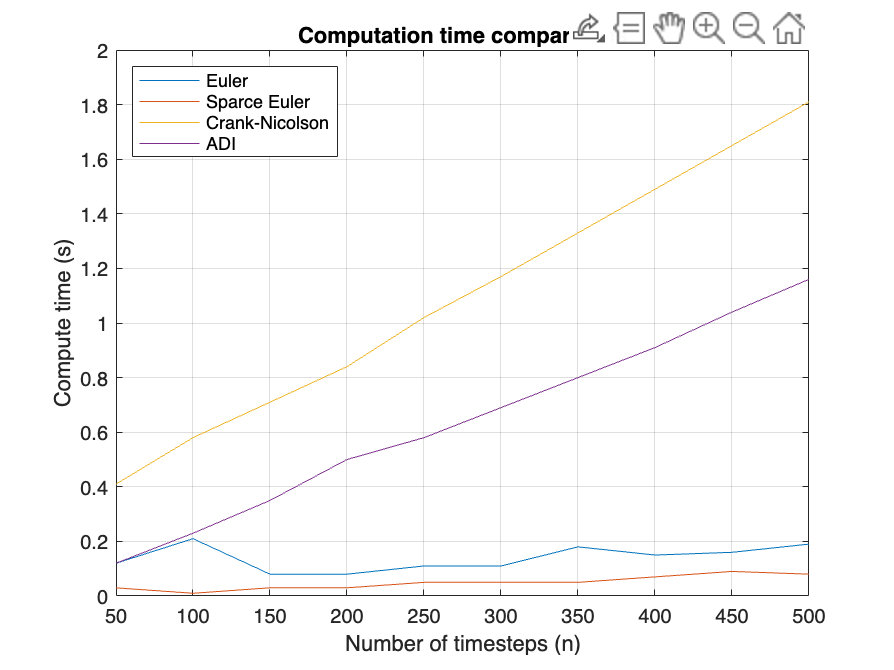

plot(nVec, tEuler)
hold on
plot(nVec, tEulerS)
plot(nVec, tCN)
plot(nVec, tADI)
hold off

grid
title("Computation time comparisons")
legend("Euler","Sparce Euler","Crank-Nicolson","ADI",location="northwest")
xlabel("Number of timesteps (n)")
ylabel("Compute time (s)")